**PART B - Image Compression**

**B.1.**

Fonction main_compression qui prend le nom du fichier bitmap, le facteur de  qualité souhaité (ie le facteur de quantization) -> utilise une première fonction imageRGBdouble

qui va prendre l'image bitmap et récupérer la matrice des coeffs RGB

Ensuite la fonction conversion_spatial_frequantiel va utiliser notre matrice RGB pour créer une matrice de quantization, en utilisant la fonction mat_quant qui crée la matrice initiale et selon le facteur de qualité, et la  fonction ajoute pour retrancher des valeurs à la matrice d'entrée, nécessaire au processus de quantization.

Enfin, on utilise la fonction ecriture_jpg qui renvoie notre image compressée.

**B.2.**

Means = zeros(1,25);
Sums = zeros(1,25);
orig = imread('Nature.bmp');
for p = 1:25
    % Création du fichier compressé/décompressé

 %   nomArriveeJPG = sprintf('NatureJPG_qualite_%d.jpg', p);
 %   main_compression(p,'Nature.bmp', nomArriveeJPG);
    main_compression(p,'Nature.bmp', 'Nature.jpg');
 %   nomArriveeBMP = sprintf('NatureBMP_qualite_%d.bmp', p);
 %   main_decompression(nomArriveeJPG, nomArriveeBMP);
    main_decompression('Nature.jpg', 'Nature2.bmp');
 %   arriv = imread(nomArriveeBMP);
    arriv = imread('Nature2.bmp');
    
    
    diff = abs(orig(1:680,:,:) - arriv(:,:,:)); % Matrice des différences en val abs
    meanDiff = mean(mean(mean(diff))) % Moyenne des termes de diff
    sumDiff = sum(sum(sum(diff))) % Somme des termes de diff
    
    Means(p) = meanDiff;
    Sums(p) = sumDiff;

end

meanDiff = 5.3519e-04

sumDiff = 1118

meanDiff = 0.8193

sumDiff = 1711470

meanDiff = 1.0374

sumDiff = 2167066

meanDiff = 1.1789

sumDiff = 2462763

meanDiff = 1.4245

sumDiff = 2975742

meanDiff = 1.5399

sumDiff = 3216718

meanDiff = 1.5574

sumDiff = 3253397

meanDiff = 1.5329

sumDiff = 3202211

meanDiff = 1.8506

sumDiff = 3865817

Means
Sums

% La réponse à la question B.2. sont les arrays Means et Sums (selon la
% méthode que l'on choisie, cf question B.4. mean et standard)

**B.3.**

imgBMP = lecture_image_bmp('Nature.bmp');
nonZ = zeros(1, 25);
for i = 1:25
    M = conversion_frequentiel_spatial(imgBMP, i); %on génère la matrice DCT qualité i
    M3 = M(:,:,1) + M(:,:,2) + M(:,:,3);
    nb = sum(sum(M3 > 0)); %Compte le nombre d'occurences de 1 i.e. nos termes non nuls
    nonZ(i) = nb;
    i
    nb
end

i = 1

nb = 524855

i = 2

nb = 473310

i = 3

nb = 441168

i = 4

nb = 425950

i = 5

nb = 415104

i = 6

nb = 403415

i = 7

nb = 397116

i = 8

nb = 390826

i = 9

nb = 385989

i = 10

nb = 382109

i = 11

nb = 378537

i = 12

nb = 375262

i = 13

nb = 372290

i = 14

nb = 369299

i = 15

nb = 365926

i = 16

nb = 363124

i = 17

nb = 361137

i = 18

nb = 359353

i = 19

nb = 357722

i = 20

nb = 356274

i = 21

nb = 354887

i = 22

nb = 353525

i = 23

nb = 352029

i = 24

nb = 350862

i = 25

nb = 349858


%nonZ contient pour chaque facteur le nombre de non zéros coefficients

**B.4.**

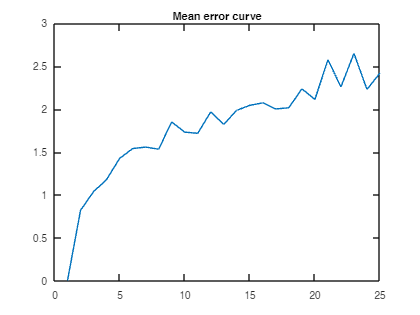

%MEAN ERROR CURVE
figure;
plot([1:25], Means);
title('Mean error curve')

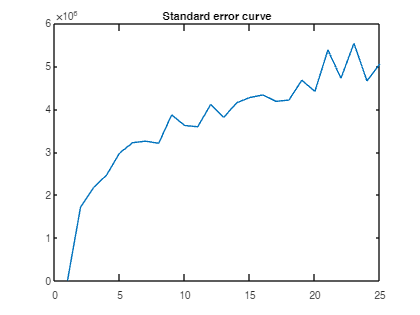


%STANDARD ERROR CURVE
figure, plot([1:25], Sums), title('Standard error curve');

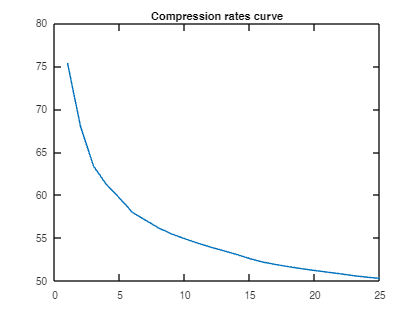


%COMPRESSION RATES CURVE
figure, plot([1:25], 100*nonZ/(680*1024)), title('Compression rates curve');